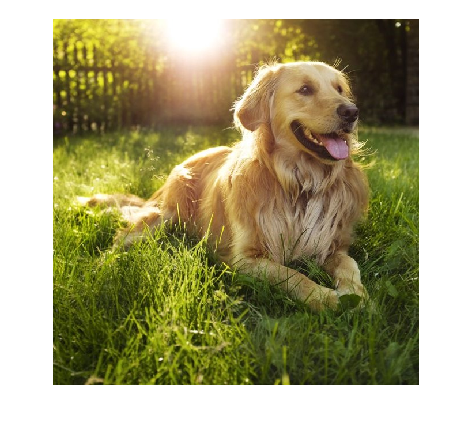

img = imread("squaredog.jpg");
imshow(img);

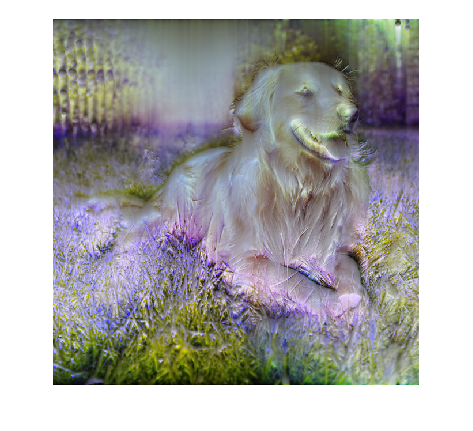


R = im2double(img(:,:,1));
G = im2double(img(:,:,2));
B = im2double(img(:,:,3));

for i = 1:635
    R(:,i) = (hilbert(R(:,i)));
    G(:,i) = (hilbert(G(:,i)));
    B(:,i) = (hilbert(B(:,i)));

end

R = rescale(angle(R),0,255);
G = rescale(angle(G),0,255);
B = rescale(angle(B),0,255);

outimg = uint8(cat(3,R,G,B));
imshow(outimg);

%colormap("gray")

%imshow();

